set(0,'DefaultTextFontname', 'LM Roman 9')
set(0,'DefaultAxesFontName', 'LM Roman 9')

pidx = [9,3];

preds_path = "C:\.matlab_workspace\.data\raw_preds\";
truth_path = "C:\.matlab_workspace\.data\ct_pt_volumes_fixed\";

truth = load(truth_path + "patient" + pidx(1) + "_day" + pidx(2) + ".mat", "spine_mask");
truth = truth.spine_mask;
ct = load(truth_path + "patient" + pidx(1) + "_day" + pidx(2) + ".mat", "ct");
ct = ct.ct;
axial_pred = load(preds_path + "axial_multiclass\" + "patient" + pidx(1) + "_day" + pidx(2) + "_axial.mat", "spine");
axial_pred = axial_pred.spine;
sagittal_pred = load(preds_path + "sagittal_multiclass\" + "patient" + pidx(1) + "_day" + pidx(2) + "_sagittal.mat", "spine");
sagittal_pred = sagittal_pred.spine;
coronal_pred = load(preds_path + "coronal_multiclass\" + "patient" + pidx(1) + "_day" + pidx(2) + "_coronal.mat", "spine");
coronal_pred = coronal_pred.spine;

% slidx = 180;
% ct2 = squeeze(ct(:, :,  slidx));
% truth2 = squeeze(truth(:, :, slidx));
% axial_pred2 = squeeze(axial_pred(:, :, slidx));
% sagittal_pred2 = squeeze(sagittal_pred(:, :, slidx));
% coronal_pred2 = squeeze(coronal_pred(:, :, slidx));
% 
% cropy = 270:330;
% cropx = 235:285;
% 
% ct2 = ct2(cropy, cropx);
% truth2 = truth2(cropy, cropx);
% axial_pred2 = axial_pred2(cropy, cropx);
% sagittal_pred2 = sagittal_pred2(cropy, cropx);
% coronal_pred2 = coronal_pred2(cropy, cropx);

% cidx = getCentroidSliceIdx(truth);
% ct2 = rot90(squeeze(ct(:, cidx,  :)));
% truth2 = rot90(squeeze(truth(:, cidx, :)));
% axial_pred2 = rot90(squeeze(axial_pred(:, cidx, :)));
% sagittal_pred2 = rot90(squeeze(sagittal_pred(:, cidx, :)));
% coronal_pred2 = rot90(squeeze(coronal_pred(:, cidx, :)));
% 
% cropy = 1:140;
% cropx = 250:335;
% 
% ct2 = ct2(cropy, cropx);
% truth2 = truth2(cropy, cropx);
% axial_pred2 = axial_pred2(cropy, cropx);
% sagittal_pred2 = sagittal_pred2(cropy, cropx);
% coronal_pred2 = coronal_pred2(cropy, cropx);

slidx = 320;
ct2 = rot90(squeeze(ct(slidx, :,  :)));
truth2 = rot90(squeeze(truth(slidx, :, :)));
axial_pred2 = rot90(squeeze(axial_pred(slidx, :, :)));
sagittal_pred2 = rot90(squeeze(sagittal_pred(slidx, :, :)));
coronal_pred2 = rot90(squeeze(coronal_pred(slidx, :, :)));

cropy = 1:130;
cropx = 210:310;

ct2 = ct2(cropy, cropx);
truth2 = truth2(cropy, cropx);
axial_pred2 = axial_pred2(cropy, cropx);
sagittal_pred2 = sagittal_pred2(cropy, cropx);
coronal_pred2 = coronal_pred2(cropy, cropx);

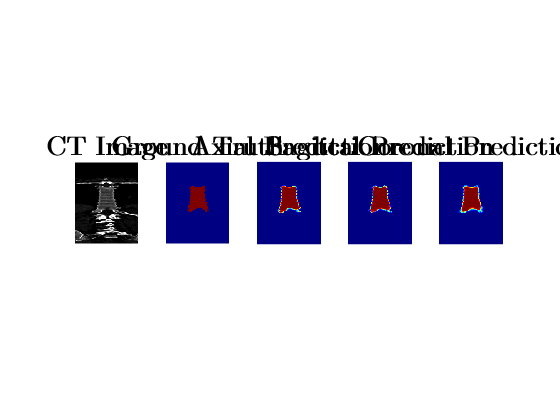


subplot(1,5,1);
imshow(ct2, [0,700], 'Colormap', gray);
title("\fontsize{20}CT Image");
subplot(1,5,2);
imshow(truth2, [], 'Colormap', jet);
title("\fontsize{20}Ground Truth");
subplot(1,5,3);
imshow(axial_pred2, [], 'Colormap', jet);
title("\fontsize{20}Axial Prediction");
subplot(1,5,4);
imshow(sagittal_pred2, [], 'Colormap', jet);
title("\fontsize{20}Sagittal Prediction");
subplot(1,5,5);
imshow(coronal_pred2, [], 'Colormap', jet);
title("\fontsize{20}Coronal Prediction");